# Hyperstate Matrix population model 

# Wandering albatross

#### By Joanie Van de Walle - 27/05/2022

### Life cycle

#### The first stage is PB1 which corresponds to chicks, age 0, at fledging). Pre-breeder stages are PB1 through PB16, with corresponding ages 0 through 15. Individuals may start transiting to the breeding stages upon PB6 (age 5) and become either SB or FB at the age of 6. Then, breeding transitions are SB, FB, PSB, PFB and NB 6 through 31, which correspond to ages 6 to 31+. However, transitions from PSB and PFB can only start from age 7 onward and transitions from NB can only start from age 8 onward.

###  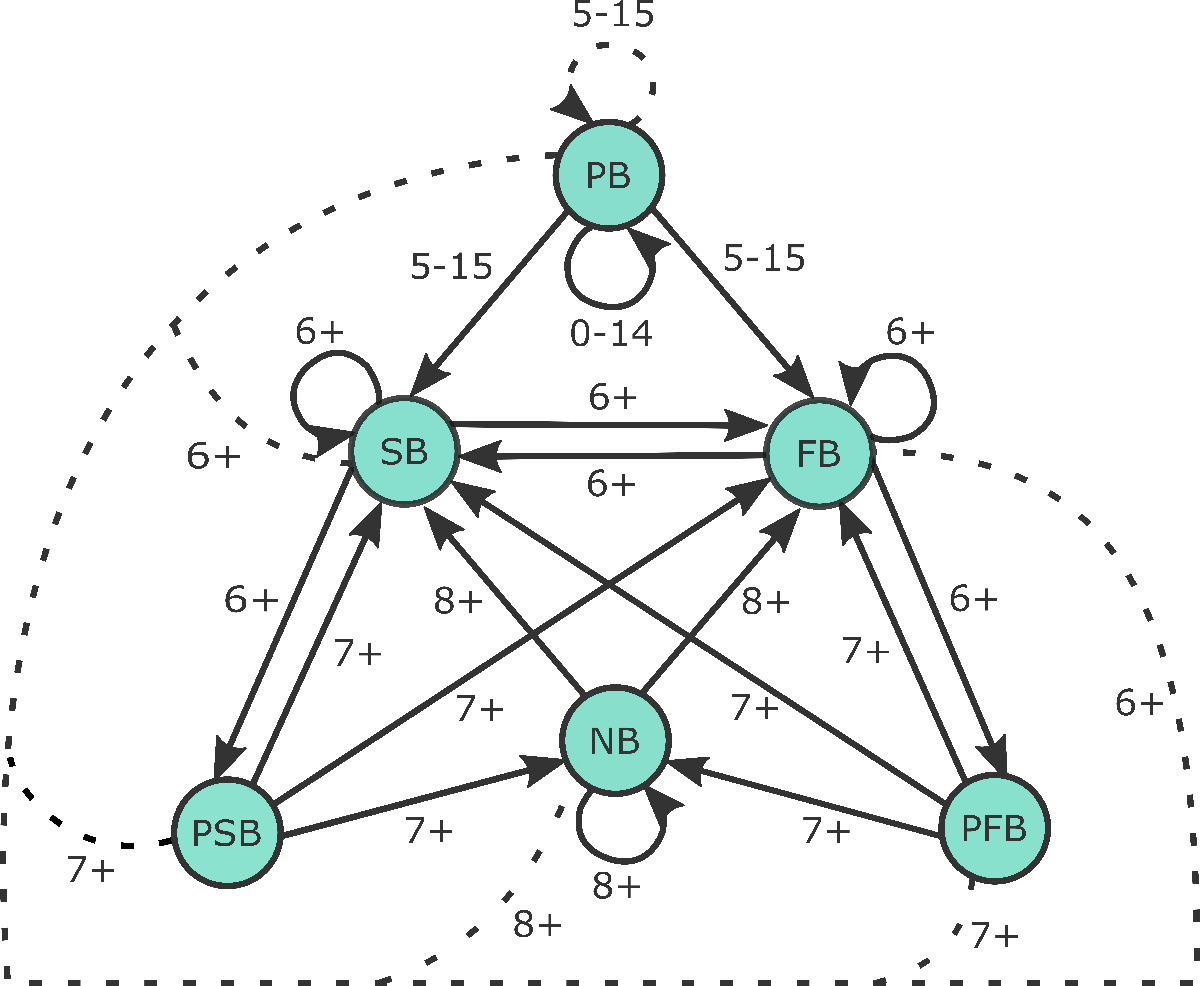

## Model construction

clc;clear;

% Load parameters
parameters

% There is an effect of personality on
% 1) survival of SB, FB, PSB, PFB, NB.
% 1) breeding probability of SB, FB, PSB, PFB, NB.
% 1) breeding success of SB, FB, PSB, PFB, NB.

% Load initial information
Info_init_6perso

% Get the personality-specific parameters
% Vector of personality effects (females, males)
ALPHA_mean= zeros(3,2); % dim1 = vital rate (survival, breeding probability, breeding success), dim2=sex (females, males)
ALPHA_mean(:,1) = [Fs_mean.alpha_Fphi_ad Fb_mean.alpha_Frho_ad Fbs_mean.alpha_Fpi_ad]; % Females
ALPHA_mean(:,2) = [Ms_mean.alpha_Mphi_ad Mb_mean.alpha_Mrho_ad Mbs_mean.alpha_Mpi_ad]; % Males

% Initiate the empty lists (one for each group of parameters)
sigma_fp_mean = zeros(w,b,g); % survival
beta_fp_mean = zeros(w,b,g); % breeding probability
gamma_fp_mean = zeros(w,b,g); % breeding success

sigma_mp_mean = zeros(w,b,g); % survival
beta_mp_mean = zeros(w,b,g); % breeding probability
gamma_mp_mean = zeros(w,b,g); % breeding success

for k = 1:g
    [sigma, beta, gamma] = parameter_personalityF(w, pb_w, b, PERSONALITY(k), ALPHA_mean(:,1), Fs_mean, Fb_mean, Fbs_mean, F_juv_mean);
    sigma_fp_mean(:,:,k) = sigma;
    beta_fp_mean(:,:,k) = beta;
    gamma_fp_mean(:,:,k) = gamma;
    
    [sigma, beta, gamma] = parameter_personalityM(w, pb_w, b, PERSONALITY(k), ALPHA_mean(:,2), Ms_mean, Mb_mean, Mbs_mean, M_juv_mean);
    sigma_mp_mean(:,:,k) = sigma;
    beta_mp_mean(:,:,k) = beta;
    gamma_mp_mean(:,:,k) = gamma;
end

% Object THETA; elements 1-3 are vital rates (survival, breeding probability and breeding success) of females of each age class (rows) and each reproductive state (cols) of each personality (3rd dimension). 4-6 are for males
THETA_mean{1} = sigma_fp_mean;
THETA_mean{2} = beta_fp_mean;
THETA_mean{3} = gamma_fp_mean;

THETA_mean{4} = sigma_mp_mean;
THETA_mean{5} = beta_mp_mean;
THETA_mean{6} = gamma_mp_mean;

% Add other relevant parameters
THETA_mean{7} = rho;
THETA_mean{8} = tau;


% Females
% Get the distirbution of personality scores and calculate phenotypic variance
perso_f = readtable("female_score.txt");
perso_f = perso_f{:,:}; % transform into a matrix
Vp=var(perso_f(:,1));

% Get the initial distribution of individuals within the different personality scores
SSD_f = get_init_dist(g, perso_f);

% Build the hyperstate population matrix
[a_f, b2_f, siz, s, A_tilde_f] = popmat_hyper(m, w, b, g, ...
    THETA_mean{1}, THETA_mean{2}, THETA_mean{3}, THETA_mean{7}, ...
    THETA_mean{8}, edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f);

for i=1:m
    U_f{i}=BD_proj_mat(a_f{i});
    F_f{i}=BD_proj_mat(b2_f{i});
end


 [wmat_f, dmat_f, vmat_f]=eig(A_tilde_f);
    lambda_f=diag(dmat_f);
    imax_f=find(lambda_f==max(lambda_f));
    lambda1_f=lambda_f(imax_f); % this is the dominant eigenvalue, i.e. population growth rate
       
    % stable age-stage distribution, w = right eigenvector
    w_vec_f=wmat_f(:,imax_f); % right eigenvector corresponding to lambda_1
    w_vec_f=w_vec_f./(sum(w_vec_f)); % normalize w to sum to 1

        perso_dist_f = zeros(1,g);
    perso_dist_f(1) = sum(w_vec_f(1:31*6));
    for i=2:g
        perso_dist_f(i) = sum(w_vec_f(31*6*(i-1)+1:31*6*i));
    end
   

% Males
perso_m = readtable("male_score.txt"); 
perso_m = perso_m{:,:}; % transform into a matrix
var(perso_m(:,1));


SSD_m = get_init_dist(g, perso_m);

% get the a matrices (U, B and P) and the b2 matrices (R, F and H) 
[a_m, b2_m, siz, s, A_tilde_m] = popmat_hyper(m, w, b, g, ...
    THETA_mean{4}, THETA_mean{5}, THETA_mean{6}, THETA_mean{7}, ...
    THETA_mean{8}, edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_m);

for i=1:m
    U_m{i}=BD_proj_mat(a_m{i});
    F_m{i}=BD_proj_mat(b2_m{i});
end

 [wmat_m, dmat_m, vmat_m]=eig(A_tilde_m);
    lambda_m=diag(dmat_m);
    imax_m=find(lambda_m==max(lambda_m));
    lambda1_m=lambda_m(imax_m); % this is the dominant eigenvalue, i.e. population growth rate
       
    % stable age-stage distribution, w = right eigenvector
    w_vec_m=wmat_m(:,imax_m); % right eigenvector corresponding to lambda_1
    w_vec_m=w_vec_m./(sum(w_vec_m)); % normalize w to sum to 1

        perso_dist_m = zeros(1,g);
    perso_dist_m(1) = sum(w_vec_m(1:31*6));
    for i=2:g
        perso_dist_m(i) = sum(w_vec_m(31*6*(i-1)+1:31*6*i));
    end    

## Sensitivity analyses

1) Sensitivity to vital rates

% - run files sensitivity_lambdaSigmaF_hyper_6perso.m ...


2) Sensitivity to heritability

herit = [linspace(0,1,5), 2]';

% Females
lambdas_mean = zeros(length(herit),2); % females, males
w_mean = zeros(g, length(herit),2); % females, males

wait = waitbar(0,'Please wait...');

for h=1:length(herit)  
    [a_f, b2_f, siz, s, A_tilde_f] = popmat_hyper(m, w, b, g, ...
        THETA_mean{1}, THETA_mean{2}, THETA_mean{3}, THETA_mean{7}, ...
       herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f); 
    
    [wmat_f, dmat_f, vmat_f]=eig(A_tilde_f);
    lambda_f=diag(dmat_f);
    imax_f=find(lambda_f==max(lambda_f));
    lambda1_f=lambda_f(imax_f); % this is the dominant eigenvalue, i.e. population growth rate
    lambdas_mean(h,1) = lambda1_f;
    
    % stable age-stage distribution, w = right eigenvector
    w_vec_f=wmat_f(:,imax_f); % right eigenvector corresponding to lambda_1
    w_vec_f=w_vec_f./(sum(w_vec_f)); % normalize w to sum to 1
    
    perso_dist_f = zeros(1,g);
    perso_dist_f(1) = sum(w_vec_f(1:31*6));
    for i=2:g
        perso_dist_f(i) = sum(w_vec_f(31*6*(i-1)+1:31*6*i));
    end
    w_mean(:,h,1) = perso_dist_f;
    
   % Males
     [a_m, b2_m, siz, s, A_tilde_m] = popmat_hyper(m, w, b, g, ...
        THETA_mean{4}, THETA_mean{5}, THETA_mean{6}, THETA_mean{7}, ...
        herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_m);
     
    [wmat_m, dmat_m, vmat_m]=eig(A_tilde_m);
    lambda_m=diag(dmat_m);
    imax_m=find(lambda_m==max(lambda_m));
    lambda1_m=lambda_m(imax_m); % this is the dominant eigenvalue, i.e. population growth rate
    lambdas_mean(h,2) = lambda1_m;
    
    % stable age-stage distribution, w = right eigenvector
    w_vec_m=wmat_m(:,imax_m); % right eigenvector corresponding to lambda_1
    w_vec_m=w_vec_m./(sum(w_vec_m)); % normalize w to sum to 1
    
    perso_dist_m = zeros(1,g);
    perso_dist_m(1) = sum(w_vec_m(1:31*6));
    for i=2:g
        perso_dist_m(i) = sum(w_vec_m(31*6*(i-1)+1:31*6*i));
    end
    w_mean(:,h,2) = perso_dist_m;   
    
    waitbar(h/length(herit))
end
close(wait)

% save
save("lambdas_mean_herit_6perso.mat", "lambdas_mean");   
save("w_mean_herit_6perso.mat", "w_mean");   

## Simulations 

1) Changing both the slope of the relationship between vital rates and personality and heritability

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% FEMALES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
clc;clear;

% Load parameters
parameters

% Load initial information
Info_init_6perso

% array of heritability
herit = [linspace(0,1,5), 2]';

% array of selection pressure on female survival
regression = linspace(0, 0.5, 6);


%%%%%%%%%%%%%% SURVIVAL
% Initialize
SSD_test = zeros(g,length(herit), length(regression)) ;
lambda_test = zeros(length(herit), length(regression));
funct = zeros(g,length(regression));

for r=1:length(regression)
    % Get the personality-specific parameters
    ALPHA= zeros(3,1); % dim1 = vital rate (survival, breeding probability, breeding success), dim2=sex (females, males)
    ALPHA(:,1) = [regression(r) % This is survival
        0  % This is breeding probability
        0];  % This is breeding success
    
    % Initiate the empty lists (one for each group of parameters)
    sigma_fp = zeros(w,b,g); % survival
    beta_fp = zeros(w,b,g); % breeding probability
    gamma_fp = zeros(w,b,g); % breeding success
    
    for k = 1:g
        [sigma, beta, gamma] = parameter_personalityF(w, pb_w, b, PERSONALITY(k), ALPHA(:,1), Fs_mean, Fb_mean, Fbs_mean, F_juv_mean);
        sigma_fp(:,:,k) = sigma;
        beta_fp(:,:,k) = beta;
        gamma_fp(:,:,k) = gamma;
    end
 
    funct(r, :) = reshape(sigma_fp(9,2,:),1,[]); % one line is one simulation of r

    for h=1:length(herit)
        
        [a, b2, siz, s, A_tilde] = popmat_hyper(m, w, b, g, ...
            sigma_fp, beta_fp, gamma_fp, 0.5, ...
            herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f);
        
        [wmat, dmat, vmat]=eig(A_tilde);
        lambda=diag(dmat);
        imax=find(lambda==max(lambda));
        lambda1=lambda(imax); % this is the dominant eigenvalue, i.e. population growth rate
        lambda_test(h,r) = lambda1;
        
        % stable age-stage distribution, w = right eigenvector
        w_vec=wmat(:,imax); % right eigenvector corresponding to lambda_1
        w_vec=w_vec./(sum(w_vec)); % normalize w to sum to 1
        
        perso_dist = zeros(1,g);
        perso_dist(1) = sum(w_vec(1:w*b));
        for i=2:g
            perso_dist(i) = sum(w_vec(w*b*(i-1)+1:w*b*i));
        end
        SSD_test(:,h,r) = perso_dist;
        
        
    end
end

save("lambdas_herit_regressionsigma_6perso.mat", "lambda_test");   
save("w_mean_herit_regressionsigma_6perso.mat", "SSD_test");   
save("FuntionalRelationships_sigma_6perso.mat", "funct");   


%%%%%%%%%%%%%% BREEDING PROBABILITY
SSD_test = zeros(g,length(herit), length(regression)) ;
lambda_test = zeros(length(herit), length(regression));
funct = zeros(g,length(regression));

for r=1:length(regression)
    ALPHA= zeros(3,1);
    ALPHA(:,1) = [0
        regression(r)
        0];
    sigma_fp = zeros(w,b,g);
    beta_fp = zeros(w,b,g);
    gamma_fp = zeros(w,b,g);
    
    for k = 1:g
        [sigma, beta, gamma] = parameter_personalityF(w, pb_w, b, PERSONALITY(k), ALPHA(:,1), Fs_mean, Fb_mean, Fbs_mean, F_juv_mean);
        sigma_fp(:,:,k) = sigma;
        beta_fp(:,:,k) = beta;
        gamma_fp(:,:,k) = gamma;
    end
    
    funct(r, :) = reshape(beta_fp(9,4,:),1,[]);
    
    for h=1:length(herit)
        
        [a, b2, siz, s, A_tilde] = popmat_hyper(m, w, b, g, ...
            sigma_fp, beta_fp, gamma_fp, 0.5, ...
            herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f);
        
        [wmat, dmat, vmat]=eig(A_tilde);
        lambda=diag(dmat);
        imax=find(lambda==max(lambda));
        lambda1=lambda(imax);
        lambda_test(h,r) = lambda1;
        
        w_vec=wmat(:,imax);
        w_vec=w_vec./(sum(w_vec));
        
        perso_dist = zeros(1,g);
        perso_dist(1) = sum(w_vec(1:w*b));
        for i=2:g
            perso_dist(i) = sum(w_vec(w*b*(i-1)+1:w*b*i));
        end
        SSD_test(:,h,r) = perso_dist;
    end
end

save("lambdas_herit_regressionbeta_6perso.mat", "lambda_test");   
save("w_mean_herit_regressionbeta_6perso.mat", "SSD_test");   
save("FuntionalRelationships_beta_6perso.mat", "funct");   


%%%%%%%%%%%%%% BREEDING SUCCESS PROBABILITY
SSD_test = zeros(g,length(herit), length(regression)) ;
lambda_test = zeros(length(herit), length(regression));
funct = zeros(g,length(regression));
for r=1:length(regression)
    ALPHA= zeros(3,1);
    ALPHA(:,1) = [0
        0
        regression(r)];
    sigma_fp = zeros(w,b,g);
    beta_fp = zeros(w,b,g);
    gamma_fp = zeros(w,b,g);
    for k = 1:g
        [sigma, beta, gamma] = parameter_personalityF(w, pb_w, b, PERSONALITY(k), ALPHA(:,1), Fs_mean, Fb_mean, Fbs_mean, F_juv_mean);
        sigma_fp(:,:,k) = sigma;
        beta_fp(:,:,k) = beta;
        gamma_fp(:,:,k) = gamma;
    end
    funct(r, :) = reshape(gamma_fp(9,2,:),1,[]);
    for h=1:length(herit)
        [a, b2, siz, s, A_tilde] = popmat_hyper(m, w, b, g, ...
            sigma_fp, beta_fp, gamma_fp, 0.5, ...
            herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f);
        [wmat, dmat, vmat]=eig(A_tilde);
        lambda=diag(dmat);
        imax=find(lambda==max(lambda));
        lambda1=lambda(imax);
        lambda_test(h,r) = lambda1;
        w_vec=wmat(:,imax);
        w_vec=w_vec./(sum(w_vec));
        perso_dist = zeros(1,g);
        perso_dist(1) = sum(w_vec(1:w*b));
        for i=2:g
            perso_dist(i) = sum(w_vec(w*b*(i-1)+1:w*b*i));
        end
        SSD_test(:,h,r) = perso_dist;
    end
end

save("lambdas_herit_regressiongamma_6perso.mat", "lambda_test");
save("w_mean_herit_regressiongamma_6perso.mat", "SSD_test");
save("FuntionalRelationships_gamma_6perso.mat", "funct");


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% MALES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear;

% Load parameters
parameters

% Load initial information
Info_init_6perso

perso_m = readtable("male_score.txt"); % This was updated 2022-11-28 from the file WAAL_personality_BLUPS_2022.csv, which comes from Jack Thorley. The distribution is normally distributed, but should be standardizes to match the standardization in the JAGS CMR code
perso_m = perso_m{:,:}; % transform into a matrix
var(perso_m(:,1));
SSD_m = get_init_dist(g, perso_m);

% array of heritability
herit = [linspace(0,1,5), 2]';

% array of selection pressure on female survival
regression = linspace(0, 0.5, 6);

%%%%%%%%%%%%%% SURVIVAL
SSD_test = zeros(g,length(herit), length(regression)) ;
lambda_test = zeros(length(herit), length(regression));
funct = zeros(g,length(regression));
for r=1:length(regression)
    ALPHA= zeros(3,1);
    ALPHA(:,1) = [regression(r)
        0
        0];
    sigma_mp = zeros(w,b,g);
    beta_mp = zeros(w,b,g);
    gamma_mp = zeros(w,b,g);
    for k = 1:g
        [sigma, beta, gamma] = parameter_personalityM(w, pb_w, b, PERSONALITY(k), ALPHA(:,1), Ms_mean, Mb_mean, Mbs_mean, M_juv_mean);
        sigma_mp(:,:,k) = sigma;
        beta_mp(:,:,k) = beta;
        gamma_mp(:,:,k) = gamma;
    end
    funct(r, :) = reshape(sigma_mp(9,2,:),1,[]);
    for h=1:length(herit)
        [a, b2, siz, s, A_tilde] = popmat_hyper(m, w, b, g, ...
            sigma_mp, beta_mp, gamma_mp, 0.5, ...
            herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_m);
        [wmat, dmat, vmat]=eig(A_tilde);
        lambda=diag(dmat);
        imax=find(lambda==max(lambda));
        lambda1=lambda(imax);
        lambda_test(h,r) = lambda1;
        w_vec=wmat(:,imax);
        w_vec=w_vec./(sum(w_vec));
        perso_dist = zeros(1,g);
        perso_dist(1) = sum(w_vec(1:w*b));
        for i=2:g
            perso_dist(i) = sum(w_vec(w*b*(i-1)+1:w*b*i));
        end
        SSD_test(:,h,r) = perso_dist;
    end
end

save("lambdas_herit_regressionsigma_6perso_M.mat", "lambda_test");
save("w_mean_herit_regressionsigma_6perso_M.mat", "SSD_test");
save("FuntionalRelationships_sigma_6perso_M.mat", "funct");


%%%%%%%%%%%%%% BREEDING SUCCESS
SSD_test = zeros(g,length(herit), length(regression)) ;
lambda_test = zeros(length(herit), length(regression));
funct = zeros(g,length(regression));
for r=1:length(regression)
    ALPHA= zeros(3,1);
    ALPHA(:,1) = [0
        regression(r)
        0];
    sigma_mp = zeros(w,b,g);
    beta_mp = zeros(w,b,g);
    gamma_mp = zeros(w,b,g);
    for k = 1:g
        [sigma, beta, gamma] = parameter_personalityM(w, pb_w, b, PERSONALITY(k), ALPHA(:,1), Ms_mean, Mb_mean, Mbs_mean, M_juv_mean);
        sigma_mp(:,:,k) = sigma;
        beta_mp(:,:,k) = beta;
        gamma_mp(:,:,k) = gamma;
    end
    funct(r, :) = reshape(beta_mp(9,4,:),1,[]);
    for h=1:length(herit)
        [a, b2, siz, s, A_tilde] = popmat_hyper(m, w, b, g, ...
            sigma_mp, beta_mp, gamma_mp, 0.5, ...
            herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_m);
        [wmat, dmat, vmat]=eig(A_tilde);
        lambda=diag(dmat);
        imax=find(lambda==max(lambda));
        lambda1=lambda(imax);
        lambda_test(h,r) = lambda1;
        w_vec=wmat(:,imax);
        w_vec=w_vec./(sum(w_vec));
        perso_dist = zeros(1,g);
        perso_dist(1) = sum(w_vec(1:w*b));
        for i=2:g
            perso_dist(i) = sum(w_vec(w*b*(i-1)+1:w*b*i));
        end
        SSD_test(:,h,r) = perso_dist;
    end
end

save("lambdas_herit_regressionbeta_6perso_M.mat", "lambda_test");   
save("w_mean_herit_regressionbeta_6perso_M.mat", "SSD_test");   
save("FuntionalRelationships_beta_6perso_M.mat", "funct");   


%%%%%%%%%%%%%% BREEDING SUCCESS PROBABILITY
SSD_test = zeros(g,length(herit), length(regression)) ;
lambda_test = zeros(length(herit), length(regression));
funct = zeros(g,length(regression));
for r=1:length(regression)
    ALPHA= zeros(3,1);
    ALPHA(:,1) = [0
        0
        regression(r)];
    sigma_mp = zeros(w,b,g);
    beta_mp = zeros(w,b,g);
    gamma_mp = zeros(w,b,g);
    for k = 1:g
        [sigma, beta, gamma] = parameter_personalityM(w, pb_w, b, PERSONALITY(k), ALPHA(:,1), Ms_mean, Mb_mean, Mbs_mean, M_juv_mean);
        sigma_mp(:,:,k) = sigma;
        beta_mp(:,:,k) = beta;
        gamma_mp(:,:,k) = gamma;
    end
    funct(r, :) = reshape(gamma_mp(9,2,:),1,[]);
    for h=1:length(herit)
        [a, b2, siz, s, A_tilde] = popmat_hyper(m, w, b, g, ...
            sigma_mp, beta_mp, gamma_mp, 0.5, ...
            herit(h), edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_m);
        [wmat, dmat, vmat]=eig(A_tilde);
        lambda=diag(dmat);
        imax=find(lambda==max(lambda));
        lambda1=lambda(imax);
        lambda_test(h,r) = lambda1;
        w_vec=wmat(:,imax);
        w_vec=w_vec./(sum(w_vec));
        perso_dist = zeros(1,g);
        perso_dist(1) = sum(w_vec(1:w*b));
        for i=2:g
            perso_dist(i) = sum(w_vec(w*b*(i-1)+1:w*b*i));
        end
        SSD_test(:,h,r) = perso_dist;
    end
end

save("lambdas_herit_regressiongamma_6perso_M.mat", "lambda_test");   
save("w_mean_herit_regressiongamma_6perso_M.mat", "SSD_test");   
save("FuntionalRelationships_gamma_6perso_M.mat", "funct");   



## Conduct sensitivity analyses with the new W (uniform distribution of personality)

clc;clear;

% Load parameters
parameters

% There is an effect of personality on
% 1) survival of SB, FB, PSB, PFB, NB.
% 1) breeding probability of SB, FB, PSB, PFB, NB.
% 1) breeding success of SB, FB, PSB, PFB, NB.

% Load initial information
Info_init_6perso

ALPHA_mean= zeros(3,2); % dim1 = vital rate (survival, breeding probability, breeding success), dim2=sex (females, males)
ALPHA_mean(:,1) = [Fs_mean.alpha_Fphi_ad Fb_mean.alpha_Frho_ad Fbs_mean.alpha_Fpi_ad]; % Females
ALPHA_mean(:,2) = [Ms_mean.alpha_Mphi_ad Mb_mean.alpha_Mrho_ad Mbs_mean.alpha_Mpi_ad]; % Males

% Initiate the empty lists (one for each group of parameters)
sigma_fp_mean = zeros(w,b,g); % survival
beta_fp_mean = zeros(w,b,g); % breeding probability
gamma_fp_mean = zeros(w,b,g); % breeding success

sigma_mp_mean = zeros(w,b,g); % survival
beta_mp_mean = zeros(w,b,g); % breeding probability
gamma_mp_mean = zeros(w,b,g); % breeding success

for k = 1:g
    [sigma, beta, gamma] = parameter_personalityF(w, pb_w, b, PERSONALITY(k), ALPHA_mean(:,1), Fs_mean, Fb_mean, Fbs_mean, F_juv_mean);
    sigma_fp_mean(:,:,k) = sigma;
    beta_fp_mean(:,:,k) = beta;
    gamma_fp_mean(:,:,k) = gamma;
    
    [sigma, beta, gamma] = parameter_personalityM(w, pb_w, b, PERSONALITY(k), ALPHA_mean(:,2), Ms_mean, Mb_mean, Mbs_mean, M_juv_mean);
    sigma_mp_mean(:,:,k) = sigma;
    beta_mp_mean(:,:,k) = beta;
    gamma_mp_mean(:,:,k) = gamma;
end

% Object THETA; elements 1-3 are vital rates (survival, breeding probability and breeding success) of females of each age class (rows) and each reproductive state (cols) of each personality (3rd dimension). 4-6 are for males
THETA_mean{1} = sigma_fp_mean;
THETA_mean{2} = beta_fp_mean;
THETA_mean{3} = gamma_fp_mean;

THETA_mean{4} = sigma_mp_mean;
THETA_mean{5} = beta_mp_mean;
THETA_mean{6} = gamma_mp_mean;

% Add other relevant parameters
THETA_mean{7} = rho;
THETA_mean{8} = tau;

[a_f, b2_f, siz, s, A_tilde_f] = popmat_hyper(m, w, b, g, ...
    THETA_mean{1}, THETA_mean{2}, THETA_mean{3}, THETA_mean{7}, ...
    THETA_mean{8}, edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f);

for i=1:m
    U_f{i}=BD_proj_mat(a_f{i});
    F_f{i}=BD_proj_mat(b2_f{i});
end


% Get v and w, code from H. Caswel may 2023
 [wmat, dmat, vmat]=eig(A_tilde_f);
    lambda=diag(dmat);
    imax=find(lambda==max(lambda));
    lambda1=lambda(imax); % this is the dominant eigenvalue, i.e. population growth rate

% stable age-stage distribution, w = right eigenvector
w_vec=wmat(:,imax); % right eigenvector corresponding to lambda_1
w_vec=w_vec./(sum(w_vec)); % normalize w to sum to 1
save("w_vec_6Perso.mat", "w_vec")

% Run R script Uniform_SSD_Creation.R

% Import the new w_vec from R. 
load("new_w_vec_6perso_uniform.mat") % This is the uniform distribution
% Run the files sensitivity...Uniform.m

## Conduct sensitivity analyses with extreme cases of h and r

clc;clear;

% Load parameters
parameters

% There is an effect of personality on
% 1) survival of SB, FB, PSB, PFB, NB.
% 1) breeding probability of SB, FB, PSB, PFB, NB.
% 1) breeding success of SB, FB, PSB, PFB, NB.

% Load initial information
Info_init_6perso

% change heritability values
tau = 1;
slope=0.5;
regression = 0.5;


% Get the personality-specific parameters
% Vector of personality effects (females, males)
ALPHA_mean= zeros(3,2); % dim1 = vital rate (survival, breeding probability, breeding success), dim2=sex (females, males)
ALPHA_mean(:,1) = [regression 0 0]; % Females
ALPHA_mean(:,2) = [Ms_mean.alpha_Mphi_ad Mb_mean.alpha_Mrho_ad Mbs_mean.alpha_Mpi_ad]; % Males

% Initiate the empty lists (one for each group of parameters)
sigma_fp_mean = zeros(w,b,g); % survival
beta_fp_mean = zeros(w,b,g); % breeding probability
gamma_fp_mean = zeros(w,b,g); % breeding success

sigma_mp_mean = zeros(w,b,g); % survival
beta_mp_mean = zeros(w,b,g); % breeding probability
gamma_mp_mean = zeros(w,b,g); % breeding success

for k = 1:g
    [sigma, beta, gamma] = parameter_personalityF(w, pb_w, b, PERSONALITY(k), ALPHA_mean(:,1), Fs_mean, Fb_mean, Fbs_mean, F_juv_mean);
    sigma_fp_mean(:,:,k) = sigma;
    beta_fp_mean(:,:,k) = beta;
    gamma_fp_mean(:,:,k) = gamma;
    
    [sigma, beta, gamma] = parameter_personalityM(w, pb_w, b, PERSONALITY(k), ALPHA_mean(:,2), Ms_mean, Mb_mean, Mbs_mean, M_juv_mean);
    sigma_mp_mean(:,:,k) = sigma;
    beta_mp_mean(:,:,k) = beta;
    gamma_mp_mean(:,:,k) = gamma;
end

% Object THETA; elements 1-3 are vital rates (survival, breeding probability and breeding success) of females of each age class (rows) and each reproductive state (cols) of each personality (3rd dimension). 4-6 are for males
THETA_mean{1} = sigma_fp_mean;
THETA_mean{2} = beta_fp_mean;
THETA_mean{3} = gamma_fp_mean;

THETA_mean{4} = sigma_mp_mean;
THETA_mean{5} = beta_mp_mean;
THETA_mean{6} = gamma_mp_mean;

% Add other relevant parameters
THETA_mean{7} = rho;
THETA_mean{8} = tau;


% Females
perso_f = readtable("female_score.txt"); % This was updated 2022-11-28 from the file WAAL_personality_BLUPS_2022.csv, which comes from Jack Thorley. The distribution is normally distributed, but should be standardizes to match the standardization in the JAGS CMR code
perso_f = perso_f{:,:}; % transform into a matrix
Vp=var(perso_f(:,1));

SSD_f = get_init_dist(g, perso_f);

[a_f, b2_f, siz, s, A_tilde_f] = popmat_hyper(m, w, b, g, ...
    THETA_mean{1}, THETA_mean{2}, THETA_mean{3}, THETA_mean{7}, ...
    THETA_mean{8}, edges_e, midpoint_e, Vp, intercept, PERSONALITY, SSD_f);

for i=1:m
    U_f{i}=BD_proj_mat(a_f{i});
    F_f{i}=BD_proj_mat(b2_f{i});
end


 [wmat_f, dmat_f, vmat_f]=eig(A_tilde_f);
    lambda_f=diag(dmat_f);
    imax_f=find(lambda_f==max(lambda_f));
    lambda1_f=lambda_f(imax_f); % this is the dominant eigenvalue, i.e. population growth rate
       
    % stable age-stage distribution, w = right eigenvector
    w_vec_f=wmat_f(:,imax_f); % right eigenvector corresponding to lambda_1
    w_vec_f=w_vec_f./(sum(w_vec_f)); % normalize w to sum to 1

% Then run the scripts sensitivity_lambdaSigmaF_hyper_6perso_Extreme ..
